# Parameters

#### Scene

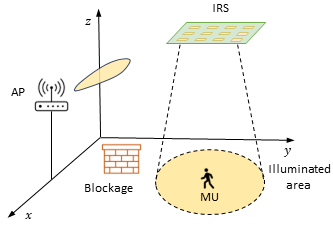

Fig. 1: Schematic illustration of IRS-assisted link.

%including the path to functions
addpath('./IRS_coeffs_functions')
addpath('./802_11ad_functions')
addpath('./AoI_functions')

p_AP = [2 0 2.5]; % BS position in meters
%The IRS is located in the yz plane and it illuminates a MU in parallel
%plane to the IRS
IRS_height=3; %IRS height in meters
p_IRS = [0 2 IRS_height]; % IRS position in meters
%The MU moves in a parallel plane to yz where the IRS is located, the
%MU moves within this plane that is (3m-MU_height) distant from the IRS as indicated
%the MU and the IRS are both oriented along the perpendicular to the
%IRS surface,which is perpendicular to the yz plane.
%by the x-coordinate in p_focus
MU_height=1.5; %MU height in meters
p_focus = [(IRS_height-MU_height) 2 3]; % center point location in meters;
                   

#### Simulation parameters

numPackets=1e3;%total of packets to transmit per position
N = 1e2; % number of points for grid discretization in the ground plane
Dobs = 10; % A D*D square observation area in the ground plane

%MU's mobility
radius_MU=5;%MU's maximum radius
total_pos_points=50;
r_MU=linspace(0,radius_MU,total_pos_points);
angle_MU=linspace(0,2*pi,total_pos_points);

#### Propagation parameters

fc = 60.48e9; % frequency
c = physconst('lightspeed'); % speed of light
lambda = c/fc; % wavelength

#### IRS parameters

Qy=160;
Qz=160;
dy = lambda/2; % element spacing
dz = lambda/2; % element spacing
Ly = Qy*dy; % IRS dimension
Lz =Qz*dz; % IRS dimension

Dp_y_tot = [1.5]; % Wide beam parameter

Dp_z_tot = Dp_y_tot; % Wide beam parameter

gtilde = 4*pi*dy*dz/(lambda^2); % unit-less unit-cell factor

%Operating regime:
D = sqrt(Ly^2+Lz^2);
dnear = sqrt(8*D^3/lambda);
dfar = 2*D^2/lambda;

#### IRS parameters

Qy=160;
Qz=160;
dy = lambda/2; % element spacing
dz = lambda/2; % element spacing
Ly = Qy*dy; % IRS dimension
Lz =Qz*dz; % IRS dimension

Dp_y_tot = [1.5]; % Wide beam parameter

Dp_z_tot = Dp_y_tot; % Wide beam parameter

gtilde = 4*pi*dy*dz/(lambda^2); % unit-less unit-cell factor

%Operating regime:
D = sqrt(Ly^2+Lz^2);
dnear = sqrt(8*D^3/lambda);
dfar = 2*D^2/lambda;

**802.11ad parameters**

**Transmitter Access Point (AP), see [3]**

Ptx_dBm = 30; % transmit power in dBm
Ptx = db2pow(Ptx_dBm-30);
% Create a configuration object for 802.11
cfgDMG = wlanDMGConfig;
%modulation format
cfgDMG.MCS="12.6";
%packet format
cfgDMG.TrainingLength = 4;   % Use 4 training subfields (TRN)
cfgDMG.PacketType = 'TRN-T';
cfgDMG.PSDULength = 2^18-1; % PSDULength in bytes, it is the largest amount of bytes within the 802.11ad std.
idleTime=20e-6;% Idle time between packets
Ngi = 64; % Fixed GI length defined in the standard (20.6.3.2.5)
%RF-interface
%beamforming parameters
total_Tx_Antenna=8;
TxArray = phased.ULA('NumElements',total_Tx_Antenna,'ElementSpacing',lambda/2);
Radiator = phased.Radiator;
Radiator.Sensor = TxArray;        % Use the uniform linear array
Radiator.WeightsInputPort = true; % Provide AWV as argument
Radiator.OperatingFrequency = fc; % Frequency in Hertz
Radiator.CombineRadiatedSignals = true; % Create plane wave


%The  antenna weight vectors (AWVs) are created using a phased. SteeringVector (Phased Array System Toolbox) object.
% Five steering angles (preamble and 4 training fields) are specified to create five AWVs,
% one for the preamble and data fields, and one for each of the four the training subfields.
% The preamble and data fields are transmitted % at boresight. The four training subfields are 
% transmitted at angles around boresight.
receiverAz = 0; % Degrees off the transmitter's boresight
% The plane wave is evaluated at a direction relative to the radiator
steerAngle = [receiverAz; 0]; % [Azimuth; Elevation]
% Create a directional steering vector object
SteeringVector = phased.SteeringVector('SensorArray',TxArray);
% The directional angle for the preamble and data is 0 degrees azimuth, no
% elevation, therefore at boresight. [Azimuth; Elevation]
preambleDataAngle = [0; 0]; 
% Each of the four training fields uses a different set of weights to steer
% to a slightly different direction. [Azimuth; Elevation]
trnAngle = [[-90; 0] [-45; 0] [45; 0] [90; 0]];
% Generate the weights for all of the angles
weights = SteeringVector(fc,[preambleDataAngle trnAngle]);
% Each row of the AWV is a weight to apply to a different antenna element
preambleDataAWV = conj(weights(:,1)); % AWV used for preamble, data and CE fields
trnAWV = conj(weights(:,2:end));      % AWV used for each TRN subfield
%figure; plotArrayResponse(TxArray,receiverAz,fc,weights);
% figure; pattern(TxArray,fc,[-90:90],0,'Type','directivity','Weights',weights);


**Receiver terminal for the mobile user (MU) as a single dipole; see [4]**

fs = wlanSampleRate(cfgDMG);%sampling time of the receiver node
BW = 2.16e9;%2*fs;%bandwidth
%RF-interface
%Create a custom antenna element using the phased.CustomAntennaElement System object.
% The antenna element has a cosine response over elevation angles from (-90°,90°).
% Plot the polar pattern response of the antenna at 1 GHz on an elevation cut at 0° azimuth.
% Display the antenna voltage response at 0° azimuth and 45° elevation.
antenna = phased.CustomAntennaElement;
antenna.AzimuthAngles = -180:180;
antenna.ElevationAngles = -90:90;
antenna.MagnitudePattern = mag2db(...
    repmat(cosd(antenna.ElevationAngles)',1,numel(antenna.AzimuthAngles)));
%pattern(antenna,fc,0,[-90:90],'Type','powerdb')
Collector = phased.Collector('Sensor',antenna,'OperatingFrequency',fc);
% figure; pattern(antenna,fc,0,[-90:90],'Type','directivity')


#### Channel Impairment

The maximum tolerance for the transmitter center frequency must be within [-20, +20] ppm [ [1](about:blank<#13%3E) ]. In this example, a clock accuracy of 20ppm is considered to derive the CFO. The transmitted signal is delayed by 500 samples and also appended by 100 zero samples at the end to account for delays from TGay channel filtering.

ppm = 20;                 % Clock accuracy to drive the CFO (ppm)
freqOffset = ppm*1e-6*fc; % Carrier frequency offset (Hz)
delay = 500;              % Sample to delay the waveform
zeroPadding = 100;        % Add trailing zeros to allow for channel delay

**Evaluating the transmitter-receiver antennas' gain**

% Generate a packet waveform
psdu = randi([0 1],cfgDMG.PSDULength*8,1);      
txWaveform = wlanWaveformGenerator(psdu,cfgDMG);

% Add delay and trailing zeros accounting for channel
% impairments
% Get the plane wave while applying the AWV to the preamble, header, and data                    
%tx = [zeros(delay,1); txWaveform; zeros(zeroPadding,1)];

%power loss in the direct link IRS-MU
Lr = (lambda/(2*pi*norm(p_focus-p_IRS)));
%performing calculations for the emission (Radiator) and reception
%(Collector) antennas
%recover the index for the data portion within the packet
ind = wlanFieldIndices(cfgDMG);
idx = (1:ind.DMGData(2));
rx = [zeros(delay,1);...
      Collector(Radiator(txWaveform(idx),steerAngle,preambleDataAWV),[0;0]);...
      zeros(zeroPadding,1)];
G_Tx_Rx_dB=pow2db(bandpower(rx)/bandpower(txWaveform(idx)));

**Frame IRS config parameters**

%IRS configuration frame
cfgDMG_config = wlanDMGConfig;
%modulation format
cfgDMG_config.MCS="12.6";
%packet format
cfgDMG_config.TrainingLength = 4;   % Use 4 training subfields (TRN)
cfgDMG_config.PacketType = 'TRN-T';
cfgDMG_config.PSDULength = ceil(32*Qy*Qz/8); % PSDULength in bytes
ind_config=wlanFieldIndices(cfgDMG_config);
T_IRS=(double(ind_config.DMGTRNCE(2))/fs);

**Frame localization parameters**

%localization time
total_blocks=11*11;
cfgDMG_loc = wlanDMGConfig;
%modulation format
cfgDMG_loc.MCS="12.6";
%packet format
cfgDMG_loc.TrainingLength = 4;   % Use 4 training subfields (TRN)
cfgDMG_loc.PacketType = 'TRN-T';
cfgDMG_loc.PSDULength = 1; % PSDULength in bytes
ind_loc=wlanFieldIndices(cfgDMG_loc);
T_loc=2*total_blocks*(double(ind_loc.DMGTRNCE(2))/fs)+total_blocks*T_IRS;

**Frame data parameters**

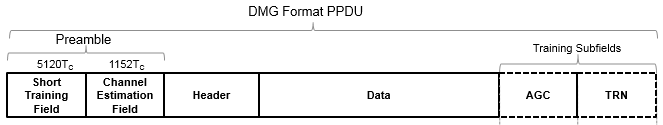

Fig. 2: Fields format of the physical layer protocol data unit (PPDU), see [1].

%recover the packet's time intervals in seconds
ind = wlanFieldIndices(cfgDMG);
%Short Training Field
T_stf = double((ind.DMGSTF(2)-ind.DMGSTF(1))+1)/fs;
%Channel Estimation Field
T_ce = double((ind.DMGCE(2)-ind.DMGCE(1))+1)/fs;
%Header
T_header = double((ind.DMGHeader(2)-ind.DMGHeader(1))+1)/fs;
%Data
T_data = double((ind.DMGData(2)-ind.DMGData(1))+1)/fs;
%Automatic Gain Control
T_agc = double((ind.DMGAGC(2)-ind.DMGAGC(1))+1)/fs;
%Automatic Gain Control subfield
T_agcsf  = double((ind.DMGAGCSubfields(1,2)-ind.DMGAGCSubfields(1,1))+1)/fs;
%Training field for the beamforming
T_trn = double((ind.DMGTRN(2)-ind.DMGTRN(1))+1)/fs;
%Training subfield for the beamforming
T_trnsf  = double((ind.DMGTRNSubfields(1,2)-ind.DMGTRNSubfields(1,1))+1)/fs*1e6;
% N = cfg.TrainingLength/4;
%Packet duration
T_ppdu=double(ind.DMGTRNCE(2))/fs;

%Reading the indices of the packet frame, used to later identify the begining and the
%end of data blocks in the wifi packet
% T_psdu=68.0364*10^(-6);

%transmission delay
T_d=(norm(p_AP-p_IRS)+norm(p_IRS-p_focus))/physconst('LightSpeed');
%coherence time
T_coh=T_ppdu;
%the values 4459 is computed as ind.DMGHeader(2)
%with the IRS_802_11_ad code
T_p_ovh=T_stf+T_ce+T_header+T_agc+T_trn;

%total of bits per radius (50 packets)
total_bits_radius=cfgDMG.PSDULength*total_pos_points*8;

#### Noise parameters; see [2]

% Noise and interference parameters
noiseFigure = 7;                             % dB
thermalNoiseDensity = -174;                  % dBm/Hz
rxInterfDensity = -165.7;                    % dBm/Hz

% Calculate the corresponding noise power
totalNoiseDensity = 10*log10(10^((noiseFigure+thermalNoiseDensity)/10)+10^(rxInterfDensity/10));
var_noise_dB = totalNoiseDensity-30+10*log10(BW); % dB
var_noise=db2pow(var_noise_dB);

**Mobility parameters for the MU**

v=1; % walking speed in [m/s] jamalis2022low paragraph after Eq. (5)
v_min_max=[0.2 1]; %minimum and maximum user's speed in m/s
total_v=100;
mean_stop=2;%stop time in seconds
% mean_stop=4;%stop time in seconds
% mean_stop=6;%stop time in seconds

%PDF for the user's velocity
v_vector=linspace(v_min_max(1),v_min_max(2),total_v);
v_max=v*fc/physconst('LightSpeed');
f_V=1/(v_min_max(2)-v_min_max(1))*ones(1,total_v);


**AoI parameters**

r_inner=[0.3 0.7 1 1.3 1.7];%inner circle radius in [m] jamalis2022low paragraph after Eq. (5)
r_outer=3;%outer circle radius in [m] jamalis2022low paragraph after Eq. (5)
delta_tau_j=0.5*10^(-4);%time granularity

**Plotting parameters**

color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html
line_width=linspace(1,3,length(color));%specify the width for each line in the plot
marker={'-','-+','-d','-.','-x','-o','-s','-*','-|','-^'};% marker symbols are given at https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html
marker_size=1:length(color);%specify the width for each marker in the plot
marker_indices=1:length(color);%specify the length between markers
fontsize=15;

#### References

[1] WLAN PPDU Structure, [https://de.mathworks.com/help/wlan/gs/dmg-ppdu-structure.html](https://de.mathworks.com/help/wlan/gs/dmg-ppdu-structure.html)

[2] Model Reconfigurable Intelligent Surfaces with CDL Channels [https://ch.mathworks.com/help/5g/ug/model-reconfigurable-intelligent-surfaces-with-cdl-channels.html](https://ch.mathworks.com/help/5g/ug/model-reconfigurable-intelligent-surfaces-with-cdl-channels.html)

[3] [https://ch.mathworks.com/help/wlan/ug/802-11ad-waveform-generation-with-beamforming.html](https://ch.mathworks.com/help/wlan/ug/802-11ad-waveform-generation-with-beamforming.html)

[4] [https://ch.mathworks.com/help/phased/ug/signal-collection.html](https://ch.mathworks.com/help/phased/ug/signal-collection.html)